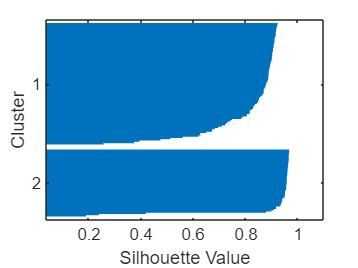

load fisheriris
[cidx2,cmeans2] = kmeans(meas,2,'dist','sqeuclidean');
[silh2,h] = silhouette(meas,cidx2,'sqeuclidean');

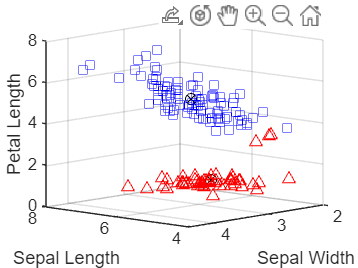

ptsymb = {'bs','r^','md','go','c+'};
for i = 1:2
    clust = find(cidx2==i);
    plot3(meas(clust,1),meas(clust,2),meas(clust,3),ptsymb{i});
    hold on
end
plot3(cmeans2(:,1),cmeans2(:,2),cmeans2(:,3),'ko');
plot3(cmeans2(:,1),cmeans2(:,2),cmeans2(:,3),'kx');
hold off
xlabel('Sepal Length');
ylabel('Sepal Width');
zlabel('Petal Length');
view(-137,10);
grid on